filelist =["data_01-Apr-2025_15-56-19.mat"
"data_01-Apr-2025_16-06-34.mat"
"data_01-Apr-2025_16-30-31.mat"  
]

filelist = 3×1 string array
    "data_01-Apr-2025_15-56-19.mat"
    "data_01-Apr-2025_16-06-34.mat"
    "data_01-Apr-2025_16-30-31.mat"




noise_file = load("lab4\lab\scenario.mat");
noise = noise_file.WhiteNoise{1}.Data;

noise =     0.6646
   -0.7005
    0.3591
    0.5002
   -0.9702
   -0.7155
   -0.9387
    0.6174
   -0.9057
    0.3324



% for exp_id =1:1 %length(filelist)
%     filename = "lab4/data/"+filelist(exp_id);
%     data = load(filename).data;
%     t = data(1,:);
%     y = data(2,:);
%     u = data(6,:);
%     if exp_id==1
%         exp = iddata(y',u',1/500);
%     else
%         exp_t = iddata(y',u',1/500);
%         exp = merge(exp,exp_t);
%     end
% end
omTSf = {noise};
tend_d=0;
do_plots = true;
bias_angle = deg2rad(7);
amp = 2;

tableofData = [];
for exp_id = 2:2
    filename = "lab4/data/"+filelist(exp_id);
    data = load(filename).data;
    time = data(1,:);
    S_out = (data(2,:))/amp; % u is output

    omeTs=resample(omTSf{exp_id},time);
    S_in = omeTs.Data; % ref is normalized input

    slices = sliceTimeSeries(time,om);
    
    for i = 1:size(slices,2)
        if (exp_id ==2 && (i==1 ||i==12) ) || (exp_id ==1 && (i==29 ||i==30))

        slices{i}.phase = NaN;
        slices{i}.gain = NaN;
        slices{i}.phase_del = NaN;
            continue
        end
        omega = slices{i}.f;
        focus = slices{i};
    
        t_start_idx = time2index(focus.t_start+tstart_d);
        t_end_idx = time2index(focus.t_end-tend_d);
       
    
        t_focus= time(t_start_idx:t_end_idx);
        om_focus= om(t_start_idx:t_end_idx);
        i_focus= S_inp(t_start_idx:t_end_idx);
        o_focus= S_out(t_start_idx:t_end_idx);
        if do_plots
            figure
            subplot(2,2,1)
                plot(t_focus,i_focus)
                title(focus.t_start + "s ->" + focus.t_end + "s")
            subplot(2,2,2)
                plot(t_focus,o_focus)
                title("Input Signal")
            subplot(2,2,[3 4])
        end
        [phase, gain, phase_del] = SweepAnalysis(t_focus,i_focus, o_focus, omega, do_plots);
        slices{i}.phase = phase;
        slices{i}.gain = gain;
        slices{i}.phase_del = phase_del;
    end
    
    [freqs,phases, gains, phase_dels] = flatten(slices);
        if do_plots
        figure
        sgtitle("Bode plot exp:" + exp_id)
        subplot(3,1,1)
        scatter(freqs,gains)
        xscale("log")
        title("Gain")
        xlabel("rad/s")
        % ylim([0.9, 1.1])

        
        subplot(3,1,2)
        scatter(freqs,rad2deg(phases))
        xscale("log")
        % ylim([0 90])
        title("Phase from Cross Corr")
        xlabel("rad/s")
        ylabel("deg")
        
        
        subplot(3,1,3)
        scatter(freqs,rad2deg(phase_dels))
        xscale("log")
        % ylim([0 90])
        title("Phasefrom Delay")
        xlabel("rad/s")
        ylabel("deg")
    end
    %
    % Save file
    tableofData = [tableofData; [freqs; phases; gains]' ];



end

% exp
tf_sm0 = tfest(exp,2,0)


tf_sm0 =
 
  From input "u1" to output "y1":
         -27.92
  ---------------------
  s^2 + 20.99 s + 11.08
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "exp".
Fit to estimation data: 64.98%                  
FPE: 0.0009174, MSE: 0.0009157                  
 
Model Properties


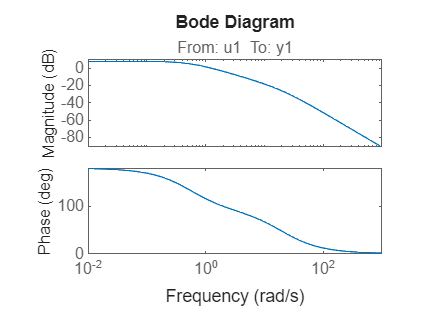

bodeplot(tf_sm0)


[g_s_id,p_s_id,ome_s_id] = bode(tf_sm0,{1,40});
ang_s_id = 1*(reshape(p_s_id(1,1,:),1,[]));
g_s_f_id = reshape(g_s_id(1,1,:),1,[]);

% theory
mu = -1.4479;
tau =  0.0401;
kp = -21.6;
kd = -0.423;

G = tf([mu],[tau 1 0]);
C = pid(kp,0,kd);
% L=G*C;
S = feedback(G,C,-1);
S_d = c2d(S,1/500);
[g_s,p_s,ome_s] = bode(S_d,{1,40});
ang_s = 1*(reshape(p_s(1,1,:),1,[]));
g_s_f = reshape(g_s(1,1,:),1,[]);

zpk(S)


ans =
 
         -36.107
  ----------------------
  (s^2 + 40.21s + 779.9)
 
Continuous-time zero/pole/gain model.
Model Properties


% bodemag(S)

## PLOTS

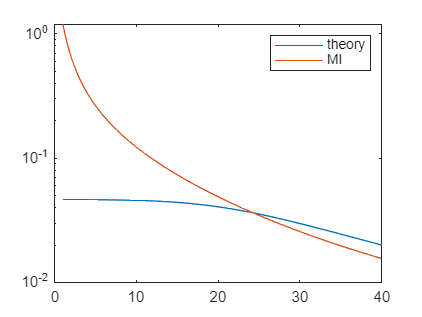

figure
plot(ome_s,g_s_f)
hold on
plot(ome_s_id,g_s_f_id)
yscale("log")
legend(["theory","MI"])